Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);

cleaned = medfilt2(x, [2 3]);
imshow(x)
figure
imshow(cleaned)


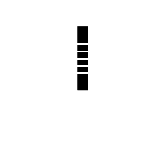

Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);
W = x((160:230), (162:200));
Map = zeros(71,500);
Map(1:71, 1:39) = W;
Map(20:21, :) = 1;
Map(28:29, :) = 1;
Map(36:37, :) = 1;
Map(44:45, :) = 1;
Map(52:53, :) = 1;
BackGroundNote = Map(:, 40:51);
imshow(BackGroundNote)

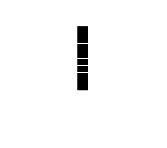


Map2 = zeros(71,500);
Map2(1:71, 1:39) = W;
Map2(20, :) = 1;
Map2(28, :) = 1;
Map2(36, :) = 1;
Map2(44, :) = 1;
Map2(52, :) = 1;
BackGroundNote2 = Map2(:, 40:51);
imshow(BackGroundNote2)

Yrange = 71;
Xrange = 12;
sz = size(TestMap);

ans = 72×13 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0


for row = 1 : (sz(1) - Yrange - 1)
    for col = 1 : (sz(2) - Xrange - 1)
        if (TestMap(row:(row + Yrange - 1), col:(col + Xrange - 1)) & BackGroundNote2) == BackGroundNote2
            g = 'a';
            
            
            
        end
    end
end


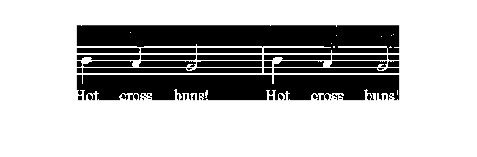

TestMap = x(150:240, 168:660);
TestMap3 = x(155:240, 220:590);
imshow(TestMap3)

function [BW,maskedRGBImage] = createMask2(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 17-May-2022
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.009;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.810;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
